# Drinking container classifier

This is an image classifier that classifies a drinking container to either bottle, drink can, drink box, or cup.

load('matlab.mat');

## Try it out!

Insert your image in the imread bracket. Please make sure you have uploaded the image in the folder before running

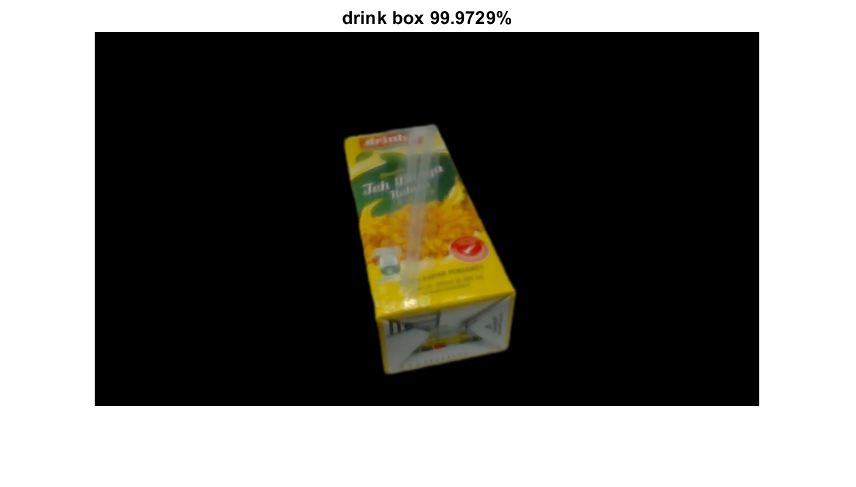

guess=imread("d box.png");
adjust=augmentedImageDatastore(inputSize(1:2),guess);

[i,score]=classify(newNet,adjust);

str = string(i)+" "+score(i)*100+"%";
figure
imshow(guess)
title(str)